**Regression Problems**

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

data = [   -5.0000  -96.2607 
   -4.8000  -85.9893
   -4.6000  -55.2451
   -4.4000  -55.6153
   -4.2000  -44.8827
   -4.0000  -24.1306
   -3.8000  -19.4970
   -3.6000  -10.3972
   -3.4000   -2.2633
   -3.2000    0.2196
   -3.0000    4.5852
   -2.8000    7.1974
   -2.6000    8.2207
   -2.4000   16.0614
   -2.2000   16.4224
   -2.0000   17.5381
   -1.8000   11.4895
   -1.6000   14.1065
   -1.4000   16.8220
   -1.2000   16.1584
   -1.0000   11.6846
   -0.8000    5.9991
   -0.6000    7.8277
   -0.4000    2.8236
   -0.2000    2.7129
         0    1.1669
    0.2000   -1.4223
    0.4000   -3.8489
    0.6000   -4.7101
    0.8000   -8.1538
    1.0000   -7.3364
    1.2000  -13.6464
    1.4000  -15.2607
    1.6000  -14.8747
    1.8000   -9.9271
    2.0000  -10.5022
    2.2000   -7.7297
    2.4000  -11.7859
    2.6000  -10.2662
    2.8000   -7.1364
    3.0000   -2.1166
    3.2000    1.9428
    3.4000    4.0905
    3.6000   16.3151
    3.8000   16.9854
    4.0000   17.6418
    4.2000   46.3117
    4.4000   53.2609
    4.6000   72.3538
    4.8000   49.9166
    5.0000   89.1652];

x = data(:,1);
y = data(:,2);
l = length(x);
n = 4; % n-1 = 3 

% Vandermonde Matrix
A = zeros(l,n);

for i = 1:n
    A(:,i) = x.^(i-1);
end


a) Find the best approximating polynomial of degree 3 w.r.t. ∥ · ∥2.

z_2 = (A'*A)\(A'*y);
y_2 = A*z_2;

b) Find the best approximating polynomial of degree 3 w.r.t. ∥ · ∥1. 

c = [zeros(n,1)
    ones(l,1)];

D = [A -eye(l)
    -A -eye(l)];

d = [y
    -y];

% Solve linear Programming
solution_1 = linprog(c,D,d);

Optimal solution found.



z_1 = solution_1(1:n);
y_1 = A*z_1;

c) Find the best approximating polynomial of degree 3 w.r.t. ∥ · ∥∞.

c = [zeros(n,1)
    1];

D = [A -ones(l,1)
    -A -ones(l,1)];

d = [y
    -y];

solution_inf = linprog(c,D,d);

Optimal solution found.



z_inf = solution_inf(1:n);
y_inf = A*z_inf;

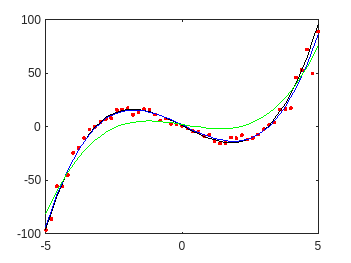

% Plot 3 Norms
plot(x,y,'r.',x,y_1,'k-', x, y_2, 'b-', x, y_inf, 'g-');